## Load Data

participants(1) = load("..\..\results\p-05\rev-02\task_results.mat");
participants(2) = load("..\..\results\p-06\rev-02\task_results.mat");
participants(3) = load("..\..\results\p-07\rev-02\task_results.mat")

participants = 1×3 struct array with fields:
    task_results


list_length = length(participants);

## Aggregate RMSE (Control)

tlo = tiledlayout(1,3);
nexttile
h1 = plot_aggregate_rmse(participants, 1, "Machine Performance", 'b', '--', 'ctrl');

nexttile
h2 = plot_aggregate_rmse(participants, 2, "Co-Adaptive Performance", 'm', '-.', 'ctrl');

nexttile
h3 = plot_aggregate_rmse(participants, 3, "Human Performance", 'r', ':', 'ctrl');

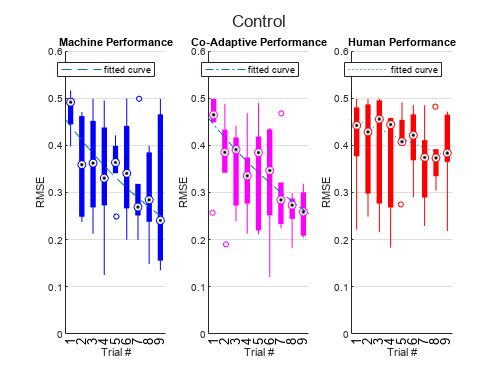

title(tlo, "Control")

## Aggregate RMSE (Experimental)

tlo = tiledlayout(1,3);
nexttile
h1 = plot_aggregate_rmse(participants, 1, "Machine Performance", 'b', '--', 'expl');

nexttile
h2 = plot_aggregate_rmse(participants, 2, "Co-Adaptive Performance", 'm', '-.', 'expl');

nexttile
h3 = plot_aggregate_rmse(participants, 3, "Human Performance", 'r', ':', 'expl');

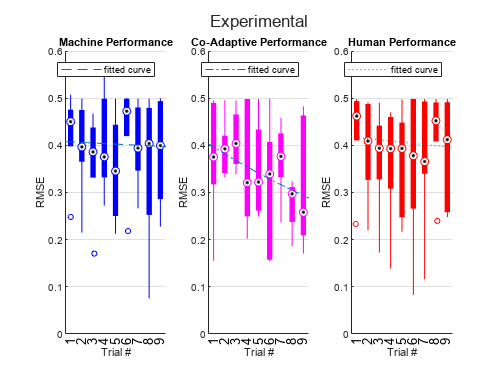

title(tlo, "Experimental")

## Number of Simulated Replicants

REPS = 3;

## Learning Rates (Control)

MODEL_SEED = [0.6, -0.2];

cond = 'ctrl';
task_coeffs = [];
for task_idx = 1:3
    rmse_tbt_aggregate = [];
    for i=1:list_length
        rmse_tbt_aggregate = [rmse_tbt_aggregate, participants(i).task_results(task_idx).rmse.(cond).int_a, participants(i).task_results(task_idx).rmse.(cond).int_b];
    end

    fig_data = rmse_tbt_aggregate;
    [n_trials, n_series] = size(fig_data);
    for i=1:n_series
        fitted_model = fit((1:1:n_trials)',fig_data(:,i),'exp1', 'StartPoint', MODEL_SEED);
        coeffs = coeffvalues(fitted_model);
        task_coeffs(task_idx,i) = coeffs(2);
    end
end
figure

l_rates_ctrl = repmat(task_coeffs,1,REPS)

l_rates_ctrl =    -0.0407   -0.0201   -0.0733   -0.0948   -0.0336   -0.0678   -0.0407   -0.0201   -0.0733   -0.0948   -0.0336   -0.0678   -0.0407   -0.0201   -0.0733   -0.0948   -0.0336   -0.0678
   -0.0285   -0.0633   -0.0672   -0.0665   -0.0608   -0.0625   -0.0285   -0.0633   -0.0672   -0.0665   -0.0608   -0.0625   -0.0285   -0.0633   -0.0672   -0.0665   -0.0608   -0.0625
    0.0195   -0.0348   -0.0038   -0.0305   -0.0207    0.0304    0.0195   -0.0348   -0.0038   -0.0305   -0.0207    0.0304    0.0195   -0.0348   -0.0038   -0.0305   -0.0207    0.0304


boxchart(l_rates_ctrl')
hold on
swarmchart(1:3, l_rates_ctrl');
hold off
[p21,h] = signrank(l_rates_ctrl(2,:), l_rates_ctrl(1,:))

p21 = 0.9478

h = logical
   0


[p23,h] = signrank(l_rates_ctrl(2,:), l_rates_ctrl(3,:))

p23 = 1.8832e-04

h = logical
   1


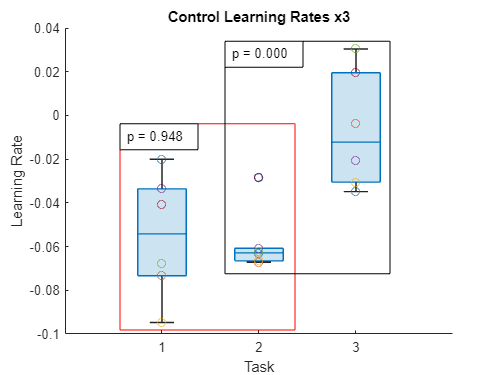

dim = [.24 .12 .35 .55];
annotation('rectangle',dim,'Color','red')
str = sprintf('p = %.3f', p21);
annotation('textbox',dim,'String',str,'FitBoxToText','on');
dim = [.45 .27 .33 .62];
annotation('rectangle',dim,'Color','black')
str = sprintf('p = %.3f', p23);
annotation('textbox',dim,'String',str,'FitBoxToText','on');

xlabel("Task")
ylabel("Learning Rate")
title(sprintf("Control Learning Rates x%d", REPS))

## Learning Rates (Experimental)

MODEL_SEED = [0.6, -0.2];

cond = 'expl';
task_coeffs = [];
for task_idx = 1:3
    rmse_tbt_aggregate = [];
    for i=1:list_length
        rmse_tbt_aggregate = [rmse_tbt_aggregate, participants(i).task_results(task_idx).rmse.(cond).int_a, participants(i).task_results(task_idx).rmse.(cond).int_b];
    end

    fig_data = rmse_tbt_aggregate;
    [n_trials, n_series] = size(fig_data);
    for i=1:n_series
        fitted_model = fit((1:1:n_trials)',fig_data(:,i),'exp1', 'StartPoint', MODEL_SEED);
        coeffs = coeffvalues(fitted_model);
        task_coeffs(task_idx,i) = coeffs(2);
    end
end
figure

l_rates_expl = repmat(task_coeffs,1, REPS)

l_rates_expl =    -0.0104   -0.0470    0.0413   -0.0006   -0.0399    0.0038   -0.0104   -0.0470    0.0413   -0.0006   -0.0399    0.0038   -0.0104   -0.0470    0.0413   -0.0006   -0.0399    0.0038
    0.0007   -0.0394    0.0227   -0.0817   -0.0635   -0.0445    0.0007   -0.0394    0.0227   -0.0817   -0.0635   -0.0445    0.0007   -0.0394    0.0227   -0.0817   -0.0635   -0.0445
    0.0231   -0.0057   -0.0448   -0.0059    0.0077    0.0077    0.0231   -0.0057   -0.0448   -0.0059    0.0077    0.0077    0.0231   -0.0057   -0.0448   -0.0059    0.0077    0.0077


boxchart(l_rates_expl')
hold on
swarmchart(1:3, l_rates_expl');
hold off
[p21,h] = signrank(l_rates_expl(2,:), l_rates_expl(1,:))

p21 = 0.0048

h = logical
   1


[p23,h] = signrank(l_rates_expl(2,:), l_rates_expl(3,:))

p23 = 0.0219

h = logical
   1


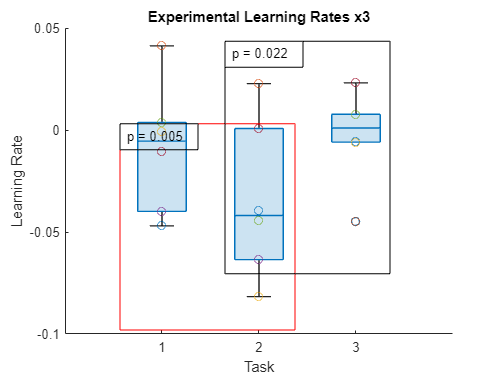

dim = [.24 .12 .35 .55];
annotation('rectangle',dim,'Color','red')
str = sprintf('p = %.3f', p21);
annotation('textbox',dim,'String',str,'FitBoxToText','on');
dim = [.45 .27 .33 .62];
annotation('rectangle',dim,'Color','black')
str = sprintf('p = %.3f', p23);
annotation('textbox',dim,'String',str,'FitBoxToText','on');

xlabel("Task")
ylabel("Learning Rate")
title(sprintf("Experimental Learning Rates x%d", REPS))

group_label = "Control";
task_label = "Machine";
rates_col = l_rates_ctrl(1,:)';
l_rates_ctrl_ml = tabularize_data(group_label, task_label, rates_col);
task_label = "CoAdapt";
rates_col = l_rates_ctrl(2,:)';
l_rates_ctrl_cl = tabularize_data(group_label, task_label, rates_col);

task_label = "Human";
rates_col = l_rates_ctrl(3,:)';
l_rates_ctrl_hl = tabularize_data(group_label, task_label, rates_col);
group_label = "Experimental";
task_label = "Machine";
rates_col = l_rates_expl(1,:)';
l_rates_expl_ml = tabularize_data(group_label, task_label, rates_col);
task_label = "CoAdapt";
rates_col = l_rates_expl(2,:)';
l_rates_expl_cl = tabularize_data(group_label, task_label, rates_col);

task_label = "Human";
rates_col = l_rates_expl(3,:)';
l_rates_expl_hl = tabularize_data(group_label, task_label, rates_col);
var_names = ["Group","Task","Learning Rates"];
data_tb = vertcat(l_rates_ctrl_hl, l_rates_ctrl_cl, l_rates_ctrl_ml, l_rates_expl_hl, l_rates_expl_cl, l_rates_expl_ml)

data_tb = 108×3 table
    group_col    task_col     vals_col 
    _________    ________    __________

    "Control"    "Human"       0.019541
    "Control"    "Human"      -0.034834
    "Control"    "Human"     -0.0037807
    "Control"    "Human"      -0.030506
    "Control"    "Human"      -0.020674
    "Control"    "Human"       0.030403
    "Control"    "Human"       0.019541
    "Control"    "Human"      -0.034834
    "Control"    "Human"     -0.0037807
    "Control"    "Human"      -0.030506
    "Control"    "Human"      -0.020674
    "Control"    "Human"       0.030403
    "Control"    "Human"       0.019541
    "Control"    "Human"      -0.034834
    "Control"    "Human"     -0.0037807
    "Control"    "Human"      -0.030506


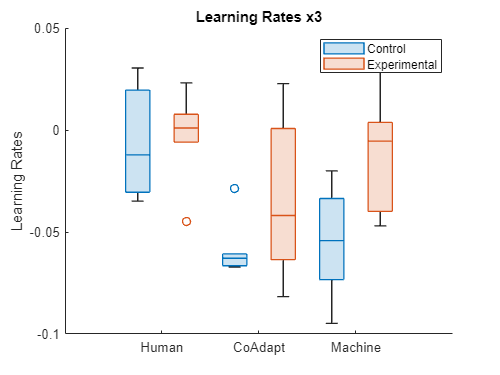

task_order = {'Human', 'CoAdapt', 'Machine'};
data_tb.task_col = categorical(data_tb.task_col, task_order);
boxchart(data_tb.task_col, data_tb.vals_col, 'GroupByColor', data_tb.group_col)
ylabel('Learning Rates')
legend
title(sprintf("Learning Rates x%d", REPS))


[p11,h] = signrank(l_rates_ctrl(1,:), l_rates_expl(1,:))

p11 = 0.0048

h = logical
   1


[p22,h] = signrank(l_rates_ctrl(2,:), l_rates_expl(2,:))

p22 = 0.0048

h = logical
   1


[p33,h] = signrank(l_rates_ctrl(3,:), l_rates_expl(3,:))

p33 = 0.3944

h = logical
   0


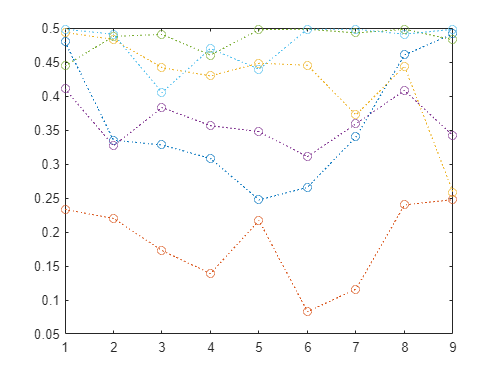

cond = 'expl';
task = 3;
figure
plot(participants(1).task_results(task).rmse.(cond).int_a, 'o:')
hold on 
plot(participants(1).task_results(task).rmse.(cond).int_b, 'o:')
plot(participants(2).task_results(task).rmse.(cond).int_a, 'o:')
plot(participants(2).task_results(task).rmse.(cond).int_b, 'o:')
plot(participants(3).task_results(task).rmse.(cond).int_a, 'o:')
plot(participants(3).task_results(task).rmse.(cond).int_b, 'o:')
hold off


figure
rmse_block = [
participants(1).task_results(task).rmse.(cond).int_a';
participants(1).task_results(task).rmse.(cond).int_b';
participants(2).task_results(task).rmse.(cond).int_a';
participants(2).task_results(task).rmse.(cond).int_b';
participants(3).task_results(task).rmse.(cond).int_a';
participants(3).task_results(task).rmse.(cond).int_b']

rmse_block =     0.4797    0.3351    0.3280    0.3081    0.2473    0.2657    0.3398    0.4605    0.4914
    0.2332    0.2199    0.1727    0.1389    0.2169    0.0828    0.1161    0.2398    0.2477
    0.4936    0.4831    0.4417    0.4295    0.4482    0.4453    0.3722    0.4438    0.2585
    0.4104    0.3267    0.3829    0.3565    0.3476    0.3107    0.3591    0.4081    0.3417
    0.4444    0.4877    0.4906    0.4601    0.4975    0.4983    0.4928    0.4982    0.4825
    0.4982    0.4908    0.4050    0.4698    0.4394    0.4982    0.4982    0.4909    0.4981


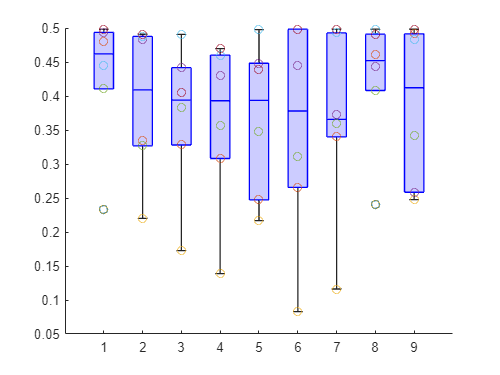

boxchart(rmse_block, BoxFaceColor='b')
hold on
swarmchart(1:9, rmse_block)
hold off

## Helper Functions

function h = plot_aggregate_rmse(participants, task_idx, series_title, series_color, l_style, rmse_field)
list_length = length(participants);
MODEL_SEED = [0.6, -0.2];
rmse_tbt_aggregate = [];

for i=1:list_length
    rmse_tbt_aggregate = cat(2, rmse_tbt_aggregate, participants(i).task_results(task_idx).rmse.(rmse_field).int_a, participants(i).task_results(task_idx).rmse.(rmse_field).int_b);
end

fig_data = rmse_tbt_aggregate';

h = boxplot(fig_data, 'PlotStyle', 'compact', 'Colors', series_color);

[~, n_trials] = size(fig_data);
model_fit = fit((1:1:n_trials)', median(fig_data,1)', 'exp1', 'StartPoint', MODEL_SEED);
hold on
plot(model_fit, l_style);
hold off

title(series_title)
ylim([0 0.6])
ylabel('RMSE')
xlabel('Trial #')
box off; grid on
end

function data_tb = tabularize_data(group_label, task_label, vals_col)
group_col = repmat(group_label, length(vals_col), 1);
task_col = repmat(task_label, length(vals_col), 1);
data_tb = table(group_col, task_col, vals_col);
end